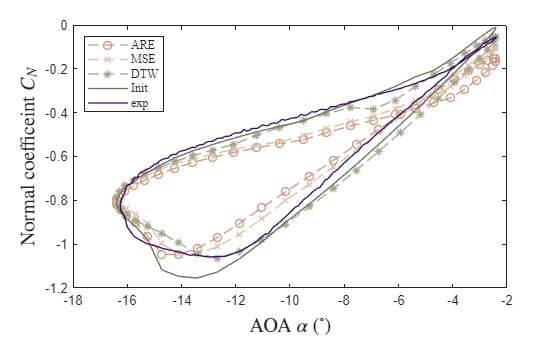

load("data_collection_ARE.mat")
ARE_data = [opt_data(1:10:end,:)
            opt_data(1,:)];
load("data_collection_DTW.mat");
DTW_data = [opt_data(1:10:end,:)
            opt_data(1,:)];
load("data_collection_MSE.mat");
MSE_data = [opt_data(1:10:end,:)
            opt_data(1,:)];

init_data = [init_data(1:10:end,:)
             init_data(1,:)];

exp_data = [exp_data
            exp_data(1,:)];

figure
fontsize = 15;
line = 1;
% plot(ARE_data(:,1) ,ARE_data(:,2) ,'o--','LineWidth',line,'Color',[237/255 179/255 39/255])
% hold on
% plot(DTW_data(:,1) ,DTW_data(:,2) ,'*--','LineWidth',line,'Color',[243/255 126/255 120/255])
% plot(MSE_data(:,1) ,MSE_data(:,2) ,'x--','LineWidth',line,'Color',[65/255  137/255 200/255])
% plot(init_data(:,1),init_data(:,2),      'LineWidth',line,'Color',[141/255 90/255  133/255])
% plot(exp_data(:,1) ,exp_data(:,2) ,      'LineWidth',line,'Color',[58/255  9/255   100/255])

plot(ARE_data(:,1) ,ARE_data(:,2) ,'o--','LineWidth',line,'Color',[203/255 153/255 126/255])
hold on
plot(MSE_data(:,1) ,MSE_data(:,2) ,'x--','LineWidth',line,'Color',[221/255 190/255 169/255])
plot(DTW_data(:,1) ,DTW_data(:,2) ,'*--','LineWidth',line,'Color',[165/255 165/255 141/255])
plot(init_data(:,1),init_data(:,2),      'LineWidth',line,'Color',[107/255 112/255 92/255])
plot(exp_data(:,1) ,exp_data(:,2) ,      'LineWidth',line,'Color',[58/255  9/255   100/255])

legend('ARE','MSE','DTW',"Init",'exp','Location', 'northwest','FontName', 'Times New Roman');
title('; ')

xlabel('AOA $\alpha$ ($^\circ$)', ... 
       'Interpreter', 'latex', ...    
       'FontName', 'Times New Roman', ...  
       'FontSize', fontsize); 

ylabel('Normal coefficeint $C_N$', ... 
       'Interpreter', 'latex', ...    
       'FontName', 'Times New Roman', ...  
       'FontSize', fontsize);
saveas(gcf, ['opt_compare','.png']);
exportgraphics(gcf,'opt_compare.pdf','ContentType', 'vector')